runtimes = [12,45,102,180,400]';
TXlengths = [2.5,5,7.5,10,15]';

lin = fit(TXlengths,runtimes,'poly1')

lin =      Linear model Poly1:
     lin(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       31.44  (18.87, 44.01)
       p2 =      -103.7  (-217.9, 10.45)

quad = fit(TXlengths,runtimes,'poly2')

quad =      Linear model Poly2:
     quad(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =       1.737  (1.651, 1.823)
       p2 =      0.6857  (-0.8721, 2.244)
       p3 =          -1  (-6.935, 4.935)

exp = fit(TXlengths,runtimes,'exp1')

exp =      General model Exp1:
     exp(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =       23.43  (3.934, 42.93)
       b =        0.19  (0.1307, 0.2493)

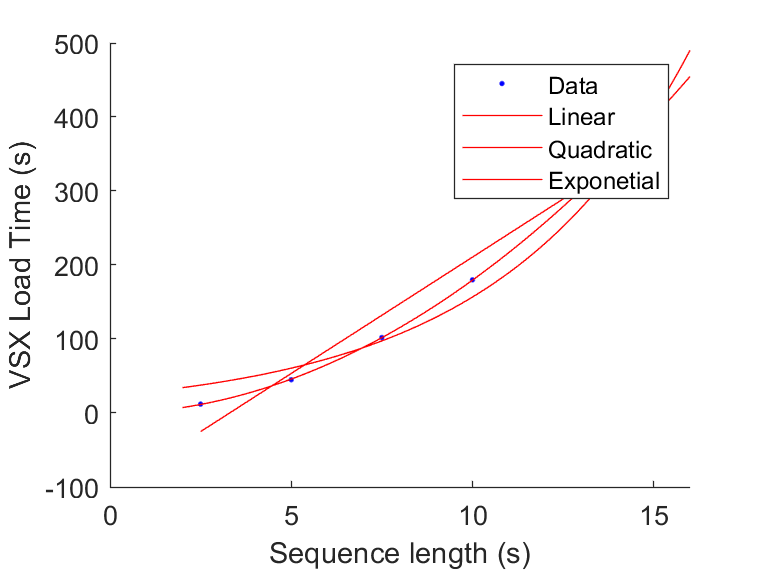


hold on
plot(lin,TXlengths,runtimes)
plot(quad) 
plot(exp) 
legend('Data','Linear','Quadratic','Exponetial')
xlabel('Sequence length (s)')
ylabel('VSX Load Time (s)')